## 卡尔曼滤波应用一

------------------------------------------------------

编写日期：2020年8月13日

版本：Matlab R2020a

作者：可爱的吾皇皇皇皇

--------------------------------------------------------

仿真信号模型：$y_{\textrm{真实}} =\;t^2 \;\left(0\le t\le 10\;\mathrm{s}\right)$

仿真传感器观测值：$y_{\textrm{观测}} =y_{\textrm{真实}} +u,\;u~N\left(0,u\right)$

% 生成真实信号
u = 1; % 传感器误差方差
dt = 0.01;
t = 0:dt:10; %　仿真时间及步长
x = t.^2; % 真实信号
rng('default'); % 保证每次随机结果一致
y = x + normrnd(0,sqrt(u),1,length(x)); % 观测信号
y = [nan y]; % 对齐状态索引

对系统进行建模1（粗糙模型）：

状态方程：$X_k =X_{k-1} +Q,\;X_0 ~N\left(0,0\ldotp 01\right),\;Q~N\left(0,Q\right)$

观测方程：$Y_k =X_k +R,\;R~N\left(0,R\right)$

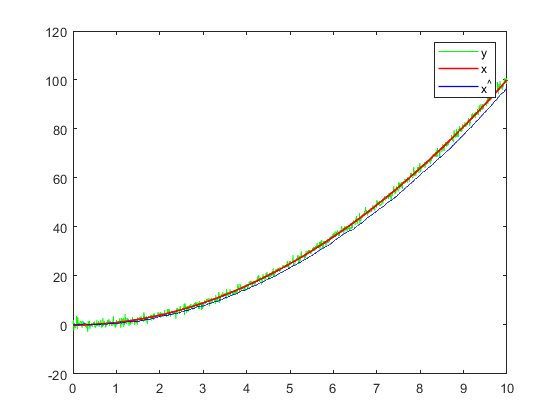

% 状态转移矩阵 观测矩阵
F = 1; H = 1;
% 过程噪声方差 观测噪声方差
% Q = 10; R = 1; % 偏向观测
Q = 0.01; R = 3; % 偏向模型
% 初始状态概率分布
mu = 0; % 均值
sigma = 0.01; % 方差
% 仿真迭代
k_max = length(t);
x_hat = zeros(1,k_max) * nan; % 保存后验概率
x_hat(1) = mu; % x0
for k = 2:k_max
    x_ = F * x_hat(k-1); % 先验（根据模型的预测值）
    % 计算后验概率
    mu = F * mu; % 先验均值
    sigma = F * sigma * F' + Q; % 先验方差
    Kal = sigma * H' / (H * sigma * H' + R); % 卡尔曼增益
    mu = mu + Kal * (y(k) - H * mu); % 后验均值
    sigma = (eye(1) - Kal * H) * sigma; % 后验方差
    x_hat(k) = mu; % 后验估计
end
% 绘图
figure; hold off;
plot(t,y(2:end),'g','LineWidth',0.8);
hold on;
plot(t,x,'r','LineWidth',1.2);
plot(t,x_hat,'b','LineWidth',1);
legend('y','x','x^\^');

norm(x_hat-x)

ans = 65.0791

对系统进行建模2（完美模型）：

状态方程：$\left\lbrack \begin{array}{c}
X_k \\
{\overset{\ldotp }{X} }_k \\
{\overset{\ldotp \ldotp }{X} }_k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & \Delta t & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X_{k-1} \\
{\overset{\ldotp }{X} }_{k-1} \\
{\overset{\ldotp \ldotp }{X} }_{k-1} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
{\Delta t}^2 \\
2\Delta t\\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
Q_1  & 0 & 0\\
0 & Q_2  & 0\\
0 & 0 & Q_3 
\end{array}\right\rbrack ,\;X_0 ~N\left(0,0\ldotp 01\right),\;Q_n ~N\left(0,Q_n \right)$

观测方程：$Y_k =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X_k \\
{\overset{\ldotp }{X} }_k \\
{\overset{\ldotp \ldotp }{X} }_k 
\end{array}\right\rbrack +R,\;R~N\left(0,R\right)$

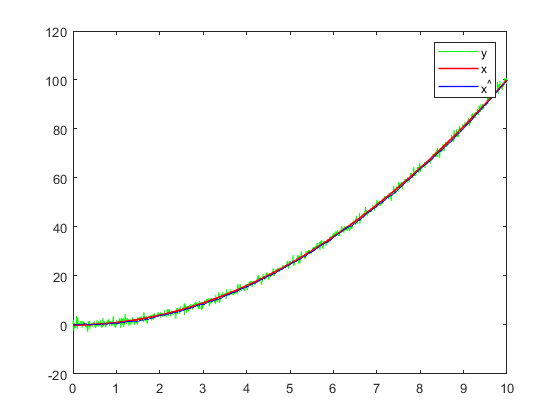

% 状态转移矩阵 观测矩阵
F = [1,dt,0;0,1,0;0,0,1]; H = [1,0,0];
% 控制量
B = [dt.^2;2*dt;0];
% 过程噪声方差 观测噪声方差
% Q1 = 10; Q2 = 10; Q3=10; R = 1; % 偏向观测
Q1 = 0.01; Q2 = 0.01; Q3=0.01; R = 1; % 偏向模型
Q = diag([Q1,Q2,Q3]);
% 初始状态概率分布
mu = [0;0;2]; % 均值
sigma = diag([0.01,0.01,0.01]); % 方差
% 仿真迭代
k_max = length(t);
x_hat = zeros(3,k_max) * nan; % 保存后验概率
x_hat(:,1) = mu; % x0
for k = 2:k_max
%     x_hat(:,k) = F * x_hat(:,k-1)+B; % 此为无噪声完美模型迭代方程
    x_ = F * x_hat(:,k-1)+B; % 先验（根据模型的预测值）
    % 计算后验概率
    mu = F * mu; % 先验均值
    sigma = F * sigma * F' + Q; % 先验方差
    Kal = sigma * H' / (H * sigma * H' + R); % 卡尔曼增益
    mu = mu + Kal * (y(k) - H * mu); % 后验均值
    sigma = (eye(3) - Kal * H) * sigma; % 后验方差
    x_hat(:,k) = mu; % 后验估计
end
% 绘图
figure; hold off;
plot(t,y(2:end),'g','LineWidth',0.8);
hold on;
plot(t,x,'r','LineWidth',1.2);
plot(t,x_hat(1,:),'b','LineWidth',1);
legend('y','x','x^\^');

norm(x_hat(1,:)-x)

ans = 16.0995